# Tests for debugging purposes

## The equations

## 
$$g(X,Q) = \sum_j \|X-Y_jQ_j\|^2 
\\
\nabla g(X,Q) = 2\bigg(\sum_j(X-Y_jQ_j), Y^\top(YQ-X)\bigg)
\\
\nabla^2 g(X,Q)[U,V] = \nabla g(U,V)$$


## Nonconvex problem

### Data and problem

clear
n=5; % data dimension
k=5; % number of matrices
r=round(n/2); % size of factorization Y of data A
p=r+1; % size of factorization X of barycenter B (r<=p)
A = data(n,k,r);
prob = nonconvex_problem(A,r,p);

### Gradient

checkgradient(prob);

The slope should be 2. It appears to be: 1.99999.
If it is far from 2, then directional derivatives might be erroneous.


The residual should be 0, or very close. Residual: 1.45656e-14.
If it is far from 0, then the gradient is not in the tangent space.
In certain cases (e.g., hyperbolicfactory), the tangency test is inconclusive.


### Hessian

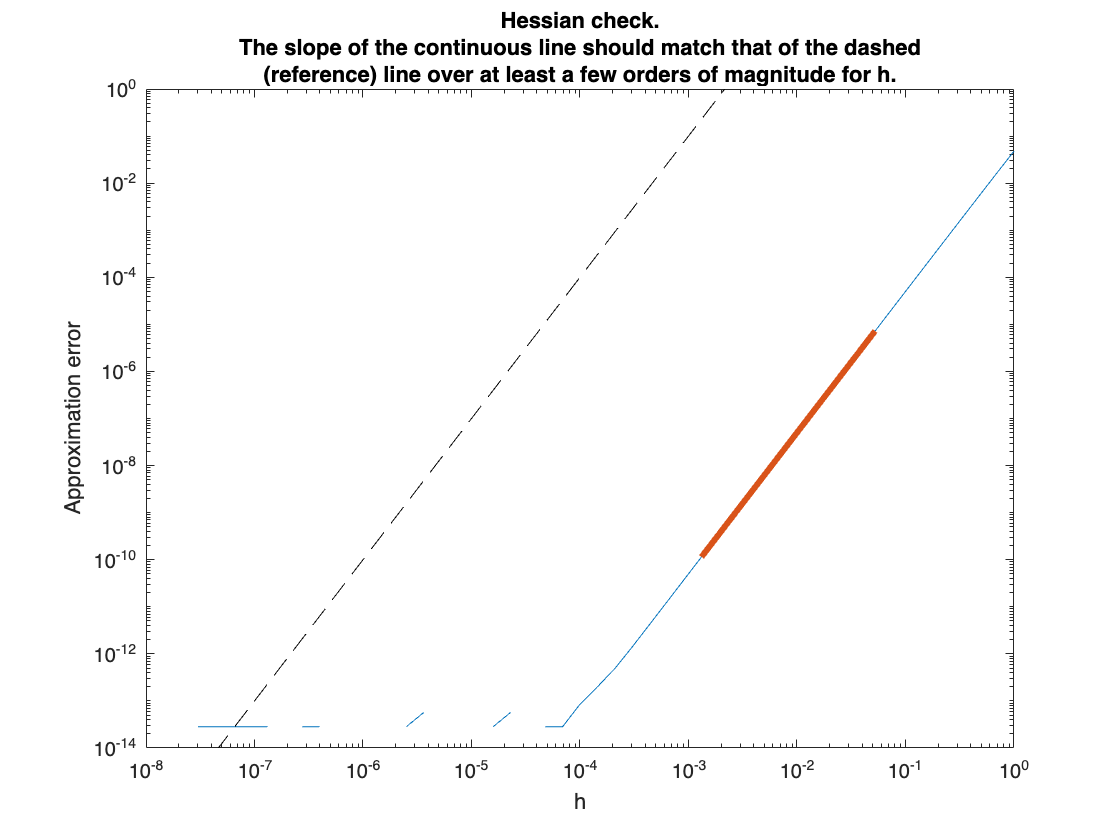

The slope should be 3. It appears to be: 2.99968.
If it is far from 3, then directional derivatives,
the gradient or the Hessian might be erroneous.
Tangency residual should be zero, or very close; residual: 1.25012e-15.
If it is far from 0, then the Hessian is not in the tangent space.
||a*H[d1] + b*H[d2] - H[a*d1+b*d2]|| should be zero, or very close.
	Value: 3.12903e-15 (norm of H[a*d1+b*d2]: 18.9015)
If it is far from 0, then the Hessian is not linear.
<d1, H[d2]> - <H[d1], d2> should be zero, or very close.
	Value: 1.3006 - 1.3006 = 8.88178e-16.
If it is far from 0, then the Hessian is not symmetric.


checkhessian(prob);

### Optimization

clear
n=10; % data dimension
k=1; % number of matrices
r=round(n/2); % size of factorization Y of data A
p=r+1; % size of factorization X of barycenter B (r<=p)
A = data(n,k,r);
prob = nonconvex_problem(A,r,p);

options.debug=0;
%options.statsfun = @variance_statsfun;
[x, xcost, info, options] = trustregions(prob,[],options);

           iter                  cost val     grad. norm    numinner     hessvec   numstored   stopreason
              0   +8.0650861776071650e+01   2.435229e+01
acc TR+       1   +5.9477757836407143e+01   1.953350e+01           1           1           1   exceeded trust region
acc TR+       2   +2.9712909931186957e+01   1.411621e+01           1           1           1   exceeded trust region
acc           3   +9.0224589078509130e+00   1.365627e+01           2           2           2   exceeded trust region
acc TR-       4   +5.7944890551619332e+00   1.138938e+01           4           4           3   exceeded trust region
acc TR+       5   +1.1244979791953034e+00   2.679282e+00           3           3           2   exceeded trust region
acc           6   +1.3187089148155510e-03   1.908071e-01           5           5           3   reached target residual-kappa (linear)
acc           7   +3.0470299311953360e-05   1.726916e-02           3           3           2   reached target residual

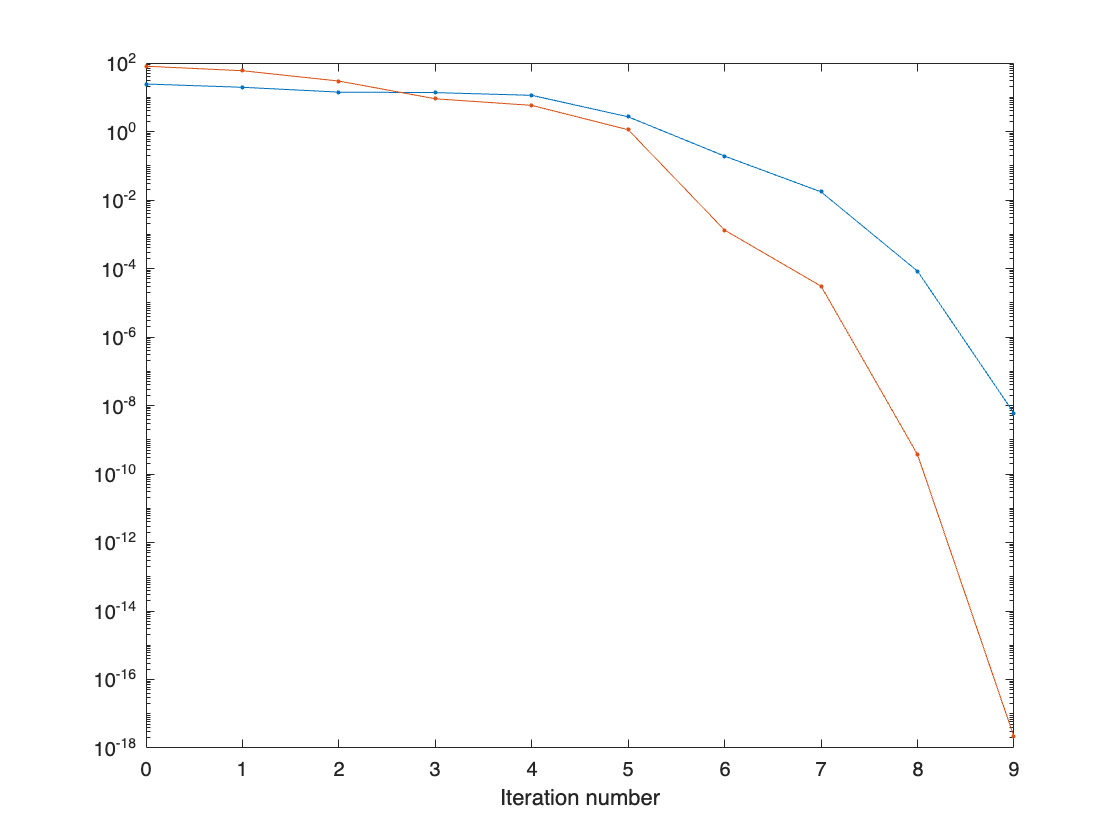

figure;
semilogy([info.iter], [info.gradnorm], '.-',[info.iter],[info.cost],'.-');
xlabel('Iteration number');

## Convex problem

### Data and problem

clear
n=4; % data dimension
k=3; % number of matrices
r=n; % size of factorization Y of data A (r>=p)
A = data(n,k,r);
prob2 = convex_problem(A);

### Gradient

checkgradient(prob2);

The slope should be 2. It appears to be: 1.
If it is far from 2, then directional derivatives might be erroneous.


The residual should be 0, or very close. Residual: 0.
If it is far from 0, then the gradient is not in the tangent space.
In certain cases (e.g., hyperbolicfactory), the tangency test is inconclusive.


### Optimization

%options.debug=1;
%options.statsfun = @variance_statsfun;
%[x, xcost, info, options] = trustregions(prob2,[],options);
% figure;
% semilogy([info.iter], [info.gradnorm], '.-',[info.iter],[info.cost],'.-');
% xlabel('Iteration number');